# First-level Stats

*Please contact Ted (huppert1@pitt.edu) or Hendrik (hes73@pitt.edu) to request more demos, suggestions, feedback, etc. We will update this script as needed. *

## 4.1 Task-based

This example show how to do the first level GLM. We recommend to use auto regressive iteratively reweighted least-squares (AR-IRLS) [default in this toolbox], to control type-I eerors in the fNIRS statistical model. See Barker et al. 2013 ([10.1364/BOE.4.001366](https://doi.org/10.1364/boe.4.001366)) for details.

clear all
clc
raw = nirs.testing.simData();

% Basic pipeline 
job = nirs.modules.Resample;
job = nirs.modules.OpticalDensity(job);
job = nirs.modules.BeerLambertLaw(job);
hb = job.run(raw);

% First level stats
job = nirs.modules.GLM();
job.type = '?'; %To see other option: OLS, NIRS-SPM, etc

type must be one of : 
OLS      
NIRS-SPM 
AR-IRLS  
MV-GLM   
Nonlinear


job.type = 'AR-IRLS';
Stats = job.run(hb);

................................Finished    1 of    1.


Our recommendation for standard analysis of fNIRS data is to do the minimum amount of manipulations to the data possible. In particular, by using statistical models that are more robust to the effects of physiology (serially-correlated errors and colored-noise) and motion-artifacts (statistical outliers), we can control false-positive rates even without removing or pre-processing these artifacts ahead of time. 

In the toolbox, there are a series of default module pipelines that represents standard minimum processing. For example, this script shows how to use the default module for single-subject analysis:

job = nirs.modules.default_modules.single_subject;
Stats = job.run(raw);

Import data module skipped: Data provided
Hb created in workspace
................................Finished    1 of    1.
SubjStats created in workspace


**SS-channel as regression**

In Santosa et al., 2020 (), we shows that the AR-IRLS regression model with SS regressors has the best performance compare with SS as prefilter. We recommend to put that SS-channel in the regressor. This example show how to use that technique. It is noted that you should have SS-channel in your probe configuration. 

clear all
clc
raw = nirs.testing.simData_shortsep();

% Basic pipeline 
job = nirs.modules.Resample;
job = nirs.modules.OpticalDensity(job);
job = nirs.modules.BeerLambertLaw(job);
hb = job.run(raw);

% First level stats
job = nirs.modules.GLM();
job.AddShortSepRegressors = true;
% This process will automatically remove the SS-channel
Stats = job.run(hb); 

................................Finished    1 of    1.


For several NIRS system, the SS-channel will be automatically labeled when you load that dataset using the toolbox. If not, this is the module to label those SS-channel

raw = nirs.testing.simData_shortsep();

job = nirs.modules.LabelShortSeperation()

job =   LabelShortSeperation with properties:

    max_distance: 15
            name: 'LabelShortSeperation'
         prevJob: []


% By default, any channel less than 15mm will be labeled as SS-channel
raw = job.run(raw);

%To check the raw data has SS-channel, see last column
raw.probe.link

ans = 50×4 table
    source    detector    type    ShortSeperation
    ______    ________    ____    _______________

      1           1       690          false     
      1           1       830          false     
      1           9       690          true      
      1           9       830          true      
      2           1       690          false     
      2           1       830          false     
      2           2       690          false     
      2           2       830          false     
      2          10       690          true      
      2          10       830          true      
      3           2       690          false     
      3           2       830          false     
      3           3       690          false     
      3           3       830          false     
      3          11       690          true   

%Check this:
raw.probe.distances

ans =    26.9258
   26.9258
    7.0711
    7.0711
   26.9258
   26.9258
   26.9258
   26.9258
    7.0711
    7.0711


**To see the results**

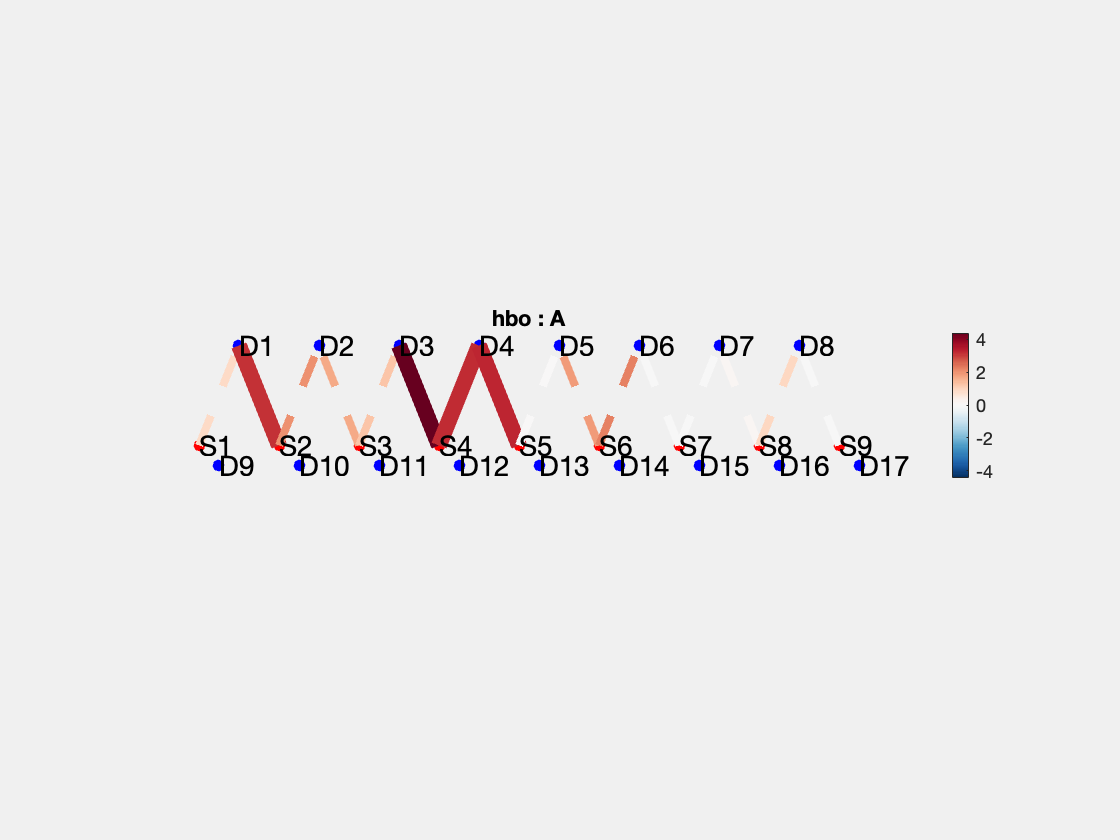

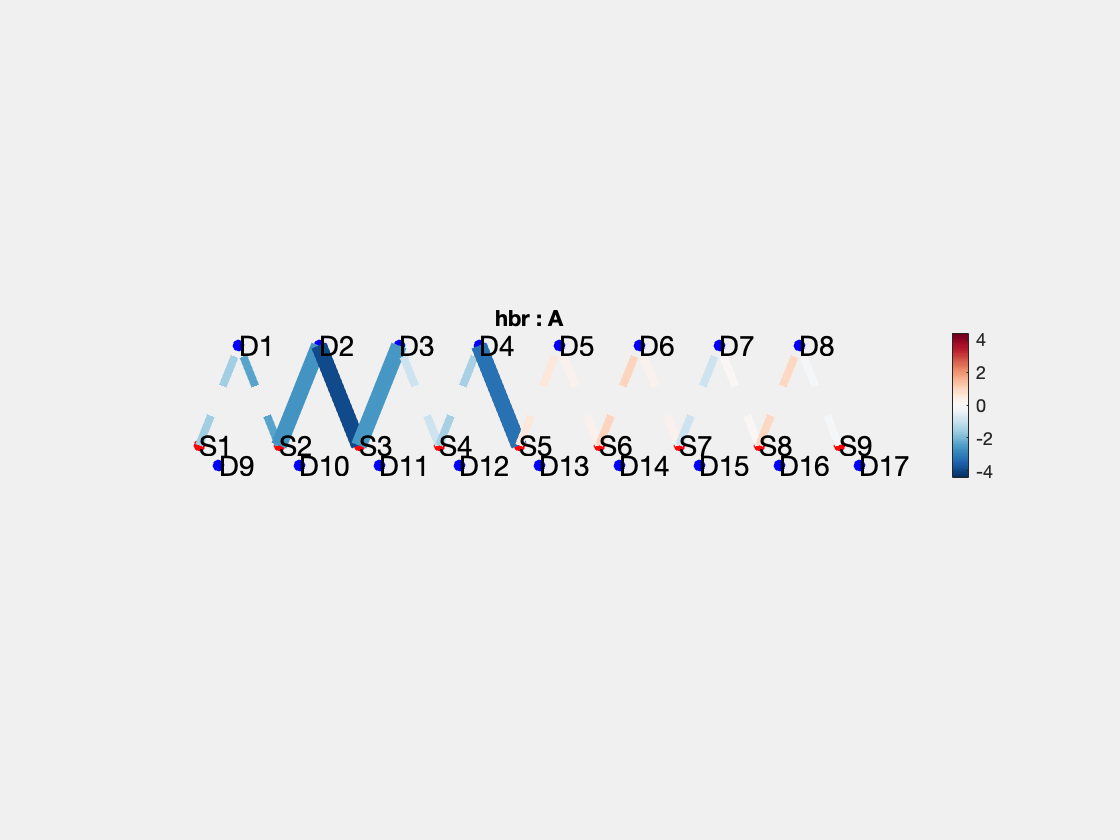

ans =   1×2 Figure array:

    Figure    Figure


Stats.draw('tstat',[],'q<0.05')

% This is showing activation maps (auto scale) hbo and hbr for q<0.05

**To see the table**

Stats.table

ans = 32×13 table
    source    detector     type      ShortSeperation    cond      beta        se       tstat      dfe          p             q         minDiscoverableChange    RelativePower
    ______    ________    _______    _______________    _____    _______    ______    _______    ______    __________    __________    _____________________    _____________

      1          1        {'hbo'}         false         {'A'}     2.9361    3.4361    0.85448    1121.4       0.39302       0.57167           8.5496               0.39294   
      1          

## 4.2 Connectivity

This example showing how to analyze the connectivity in subject level.

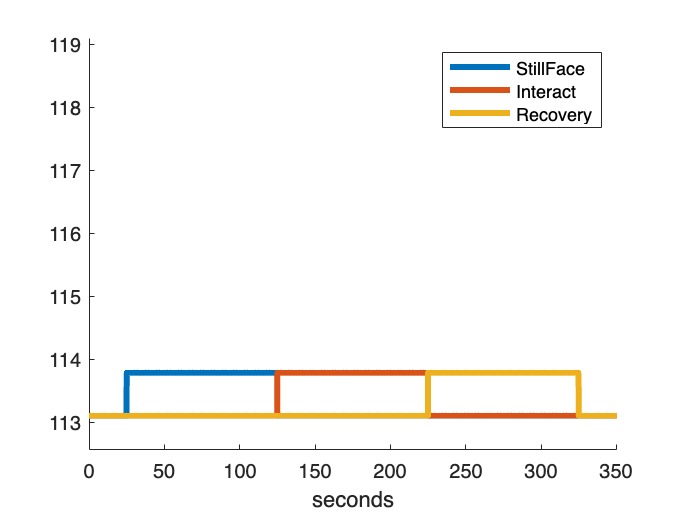

clear all
clc

load  AnalyzIR_Dataset1.mat

% For speed, just use 4 files
raw(5:end) = [];

% Let's make 3 block (StillFace, Interact, and Recovery)
for i = 1:length(raw)
    stim = nirs.design.StimulusEvents;
    stim.name = 'StillFace';
    stim.onset = 25;
    stim.dur = 100;
    stim.amp = 1;
    raw(i).stimulus('StillFace') = stim;

    stim = nirs.design.StimulusEvents;
    stim.name = 'Interact';
    stim.onset = 125;
    stim.dur = 100;
    stim.amp = 1;
    raw(i).stimulus('Interact') = stim;

    stim = nirs.design.StimulusEvents;
    stim.name = 'Recovery';
    stim.onset = 225;
    stim.dur = 100;
    stim.amp = 1;
    raw(i).stimulus('Recovery') = stim;
end

job=nirs.modules.KeepStims();
    job.listOfStims={'StillFace','Interact','Recovery'};
raw = job.run(raw);

% See this stim
figure; raw(1).draw([])



% This is the module to do connectivity analysis
job = nirs.modules.Resample();
job.Fs = 1; %For speed
job = nirs.modules.OpticalDensity(job);
job = nirs.modules.BeerLambertLaw(job);
hb = job.run(raw);

job = nirs.modules.Connectivity();
%   Connectivity with properties:
%        corrfcn: @(data)nirs.sFC.ar_corr(data,'4xFs',true)
%        name: 'Connectivity'
%        prevJob: []

% the corrfcn field is a function handle to which ever of the versions of
% correlation that we wish to use.  The default is the AR-correlation using
% robust regression and a max model order of 4x the sample rate.  
    
% Examples (correlation based)
% job.corrfcn=@(data)nirs.sFC.ar_corr(data,'4x',true); % Whitened correlation (using Pmax 4 x FS)
% job.corrfcn=@(data)nirs.sFC.corr(data,true);  % Regular correlation
% job.corrfcn=@(data)nirs.sFC.ar_wcoher(data,'4x',[.05 .2],'morl',true); % Whitened Wavelet coherence
% job.corrfcn=@(data)nirs.sFC.wcoher(data,[.05 .2],'morl',true); % Wavelet coherence

ConnStats1 = job.run(hb);

Finished 1 of 4
Finished 2 of 4
Finished 3 of 4
Finished 4 of 4



% See the final condition
ConnStats1(1).conditions

ans = 1×1 cell array
    {'rest'}



% To analyze the connectivity per conditions 
job = nirs.modules.Connectivity();
job.divide_events = true;
ConnStats2 = job.run(hb);

Spliting condition: StillFace
   1 of 1
Spliting condition: Interact
   1 of 1
Spliting condition: Recovery
   1 of 1
Finished 1 of 4
Spliting condition: StillFace
   1 of 1
Spliting condition: Interact
   1 of 1
Spliting condition: Recovery
   1 of 1
Finished 2 of 4
Spliting condition: StillFace
   1 of 1
Spliting condition: Interact
   1 of 1
Spliting condition: Recovery
   1 of 1
Finished 3 of 4
Spliting condition: StillFace
   1 of 1
Spliting condition: Interact
   1 of 1
Spliting condition: Recovery
   1 of 1
Finished 4 of 4



% See the final condition
ConnStats2(1).conditions

ans = 1×3 cell array
    {'StillFace'}    {'Interact'}    {'Recovery'}


**To see the results**

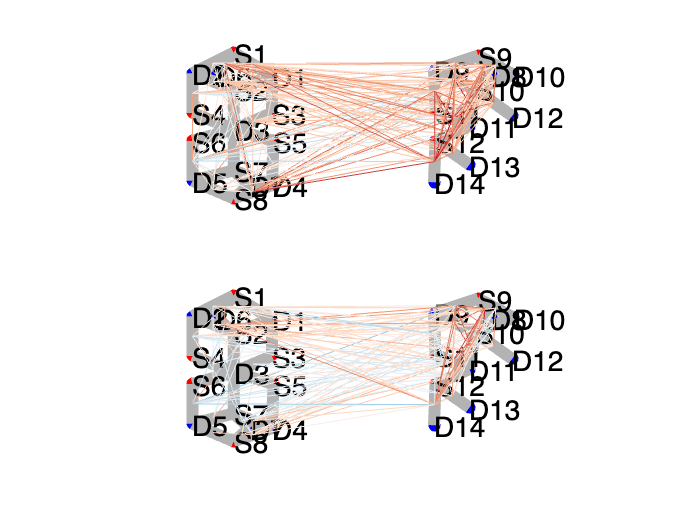

ans =   Figure (4: rest) with properties:

      Number: 4
        Name: 'rest'
       Color: [1 1 1]
    Position: [396 256 560 420]
       Units: 'pixels'

  Show all properties


% Drawing R value
ConnStats1(1).draw('R',[-1 1],'p<0.05')

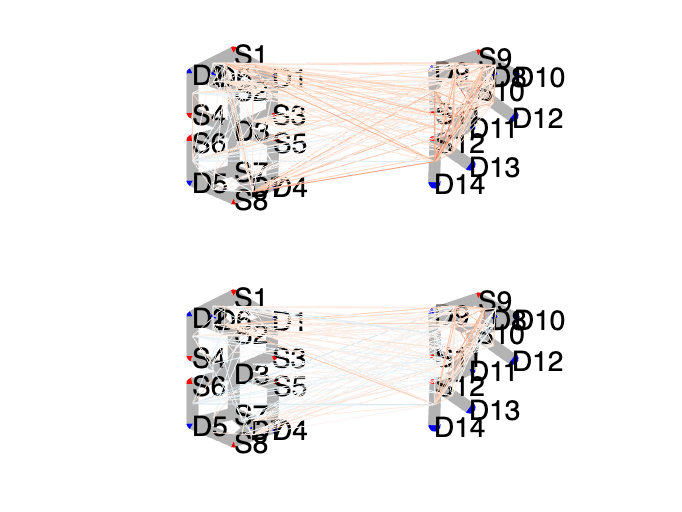

ans =   Figure (5: rest) with properties:

      Number: 5
        Name: 'rest'
       Color: [1 1 1]
    Position: [396 256 560 420]
       Units: 'pixels'

  Show all properties



% Drawing Z value
ConnStats1(1).draw('Z',[],'p<0.05')

**To see the table**

ConnStats1(1).table

ans = 4900×12 table
    condition    SourceOrigin    DetectorOrigin    TypeOrigin    SourceDest    DetectorDest    TypeDest        R            Z           t          pvalue        qvalue  
    _________    ____________    ______________    __________    __________    ____________    ________    _________    _________    ________    __________    __________

    {'rest'}          1                1            {'hbo'}          1              1          {'hbo'}             1            6         Inf             1             1
    {'rest'}          1                1            {'hbo'}  

## 4.3 Hyperscanning

This example show how to analyze hyperscanning data. In this module, we need to specify the subject pair. 

% Let's make a simple example from the previous 4 files

job = nirs.modules.Hyperscanning();
ScanA = [1 3]';  % The list of all the "A" files
ScanB = [2 4]';  % The list of all the "B" files

OffsetA = [0 0]';  % The time shift of the "A" files (in sec)
OffsetB = [0 0]';  % The time shift of the "B" files (in sec)

link = table(ScanA,ScanB,OffsetA,OffsetB);
job.link=link;

HyperStats = job.run(hb);

Finished processing dyad 1 of 2 (   50%)
Finished processing dyad 2 of 2 (  100%)


**To see the results**

% Drawing R value
% HyperStats(1).draw('Z:hbo','q<0.05')

**To see the table**

HyperStats(1).table

ans = 19600×12 table
    condition    SourceOrigin    DetectorOrigin    TypeOrigin    SourceDest    DetectorDest    TypeDest        R            Z           t          pvalue        qvalue  
    _________    ____________    ______________    __________    __________    ____________    ________    _________    _________    ________    __________    __________

    {'rest'}          1                1            {'hbo'}          1              1          {'hbo'}             1            6         Inf             1             1
    {'rest'}          1                1            {'hbo'} 